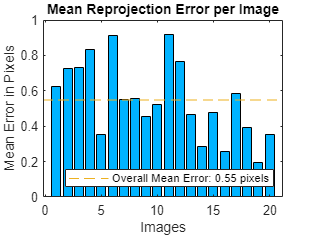

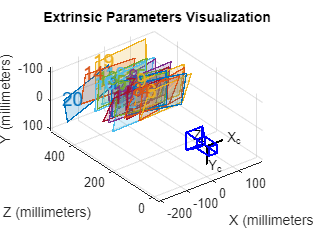


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  447.9294 +/- 6.5245      449.6906 +/- 6.4970  ]
Principal point (pixels):[  317.0547 +/- 1.3225      192.9172 +/- 2.4815  ]
Radial distortion:       [    0.0215 +/- 0.0100       -0.4400 +/- 0.0387  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0408 +/- 0.0064        0.2080 +/- 0.0049        0.0103 +/- 0.0011  ]
                         [    0.1371 +/- 0.0074        0.1460 +/- 0.0057        0.0734 +/- 0.0010  ]
                         [    0.3090 +/- 0.0062       -0.0483 +/- 0.0041        0.1086 +/- 0.0008  ]
                         [    0.1738 +/- 0.0055       -0.1452 +/- 0.0047       -0.0305 +/- 0.0010  ]
                         [    0.0468 +/- 0.0071        0.0588 +/- 0.0049        0.1030 +/- 0.0008  ]
                         [    0.2752 +/- 0.0058       -0.1273 +/- 0.0049        0.0700 +/- 0.0011  ]
 

calibrationParams;

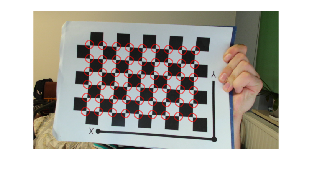

figure; 
imshow(RGB);
hold on
plot(imagePoints(:,1),imagePoints(:,2),'ro')
hold off

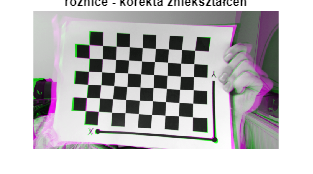

figure; 
imshowpair(RGB, undistortedImage,'falsecolor');
title('różnice - korekta zniekształceń')

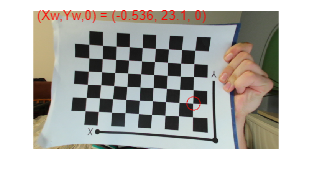

figure;
imshow(undistortedImage)
hold on
plot(myPoint1(1),myPoint1(2),'ro','MarkerSize',10)
hold off
text(10,10, ...
    ['(Xw,Yw,0) = (' num2str(myWorldPoint1(1),3) ', ' num2str(myWorldPoint1(2),3) ', 0)'],...
    'Color','red')

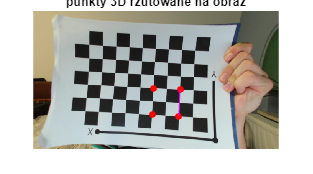

figure; 
imshow(undistortedImage);
hold on
plot(projectedPoints1(:,1), projectedPoints1(:,2),'r.','MarkerSize',15);
plot([projectedPoints1(1,1) projectedPoints1(2,1)],...
    [projectedPoints1(1,2) projectedPoints1(2,2)],'m-')
hold off
title('punkty 3D rzutowane na obraz')

myWorldPoints.Z = [1 2 2 1];
pts1             = [myWorldPoints.X(:) myWorldPoints.Y(:) myWorldPoints.Z(:)]; % (X, Y, Z - wektory kolumnowe)
projectedPoints1 = worldToImage(cameraParams, R, t, pts1);

r1 = 0.5 + sin(t1);

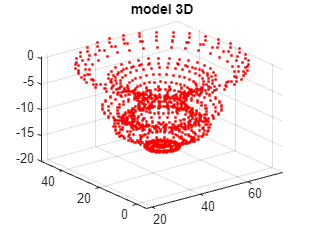

figure;
plot3(X,Y,Z,'r.')
hold off
grid on
title('model 3D')

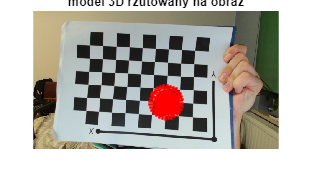


figure; 
imshow(RGB);
hold on
plot(projectedPoints1(:,1), projectedPoints1(:,2),'r.');
hold off
title('model 3D rzutowany na obraz')

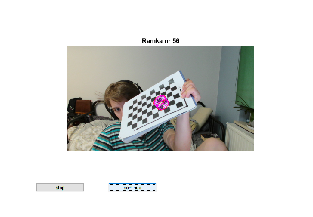

figure; 
imshow('img1.png');

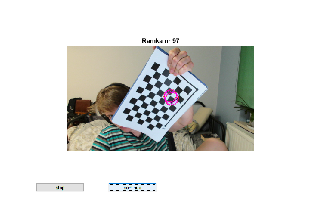

figure; 
imshow('img2.png');

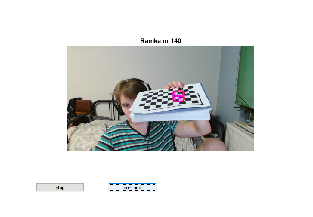

figure; 
imshow('img3.png');

Nakładanie działa bardzo dobrze, przestaje funnkcjonować dopiero przy prawie płaskim ułożeniu planszy względem kamery

Podsumowanie

Rezultaty: wyżej

Analiza:

- Wyżej

- zewnętrzne: lokalizacja kamery w scenie 3D: rotacja i przesunięcie odpowiadają za przejście parametrów 3D ze swiata w parametry 3D kamery, wewnęrzene: centrum optyczne i ogniskowa odpowiadają za transformacje z koordynatów 3D kamery w obraz 2D

Pytania

- Pozbywanie się zaburzeń soczewki - usprawnianie i polepszanie jakości zdjęć, pomiary rzeczywistych obiektów - nie trzeba do tego wykorzystywać ludzi, odtwarzanie obiektów 3D - modelowanie np. do gier czy symulacji.

- umieszczanie cylindra działało zaskakująco dobrze, sposób w jaki za pomocą zestawu parametrów przeliczamy obraz po koeli w 3 sferach i na ich podstawie możemy zrozumieć głębie wczytywanego obrazu

- Jak interpretować wykres Extrinsic parameters visualization